# Fast Fourier Transform By Hand

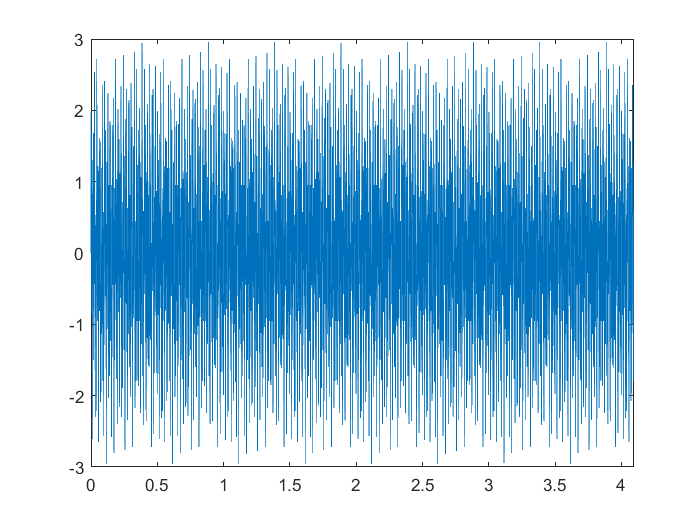

clear;clc;
dx = 0.001;
end_point = 4.095;
x = 0:dx:end_point;

fx = sin(2*pi*50*x) + sin(2*pi*120*x) + sin(2*pi*276*x);

figure(1);
plot(x,fx);
axis([0 end_point -3 3]);

## Test

N = length(fx);

tic;
fw = dft_slow(fx');
toc;

Elapsed time is 7.501290 seconds.


tic;
fw_ = fft_scratch(fx');
toc;

Elapsed time is 0.050497 seconds.


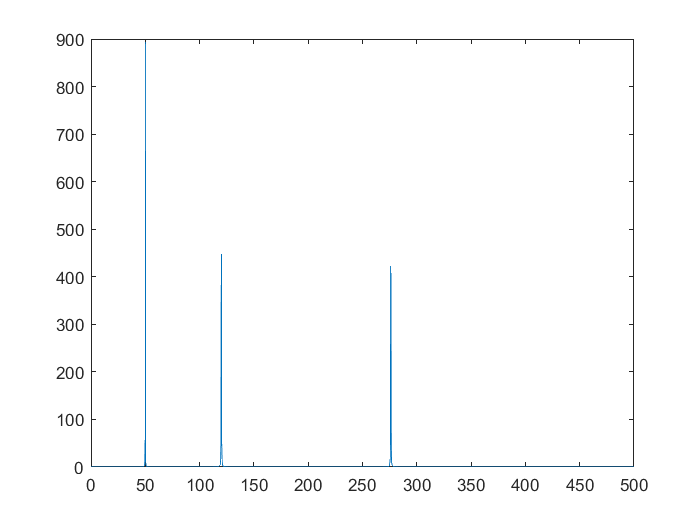


PSD = fw.*conj(fw)/N; % Power spectrum density (how much power is in each spectrum), this is just the inner product of fw iwth itself

figure(2);
plot(((1:N/2)-1)/end_point,PSD(1:N/2)); % scaling the frequencies by dividing the end_point (important)